## **MID-TERM PROJECT **

*Goal*: create a fuzzy inference system for tumor segmentation in MR images exploiting genetic algorithm based rules selection

clc;
close all;

### **Dataset**

In this section we have to extract our needed data from the given dataset

**Dowloading the dataset**

imageDir = fullfile(tempdir,"BraTS");
filename = matlab.internal.examples.downloadSupportFile(...
    "vision","data/sampleBraTSTestSetValid.tar.gz");
untar(filename,imageDir);

**Extraction of the data**

imageDir = fullfile(tempdir, "BraTS",...
    "sampleBraTSTestSetValid", "imagesTest");
labelDir = fullfile(tempdir, "BraTS",...
    "sampleBraTSTestSetValid", "labelsTest");

imageFiles = dir(fullfile(imageDir, "*.mat"));
labelFiles = dir(fullfile(labelDir, "*.mat"));

Extracting the names of the files, and delete them in: 

- imageDir

- labelDir

imageSubjects = erase({imageFiles.name}, ".mat");
labelSubjects = erase({labelFiles.name}, ".mat");

Visualizing the subjects

disp("Subjects with available images:")

Subjects with available images:


disp(imageSubjects)

    {'BraTS446'}    {'BraTS447'}    {'BraTS455'}    {'BraTS461'}    {'BraTS463'}



disp("Subjects with available labels:")

Subjects with available labels:


disp(labelSubjects)

    {'BraTS446'}    {'BraTS447'}    {'BraTS455'}    {'BraTS461'}    {'BraTS463'}



**Extracting the MR image of subject "BraTS446"**

Selecting the subject:

% Subject "BraTS446"
dataFileName = fullfile(imageDir, "BraTS446");
labelFileName = fullfile(labelDir, "BraTS446");

% Loading the data
data = load(dataFileName);
label = load(labelFileName);

Extracting a slice of the 3D MR image:

% Extract a slice of the 3D image
sliceNumber = 70;
data = data.cropVol(:, :, sliceNumber, 1);
label = label.cropLabel(:, :, sliceNumber);

Volume: 240x240x152

Slice: 240x240

### Phase 1: Development of the fuzzy Inference systems

During this phase, we have to extract the features of the image and define multiple fuzzy rules on such features to infer tumor segmentation.

**Original data**

For a basis of confrontation, below there is the printed image of the original data.

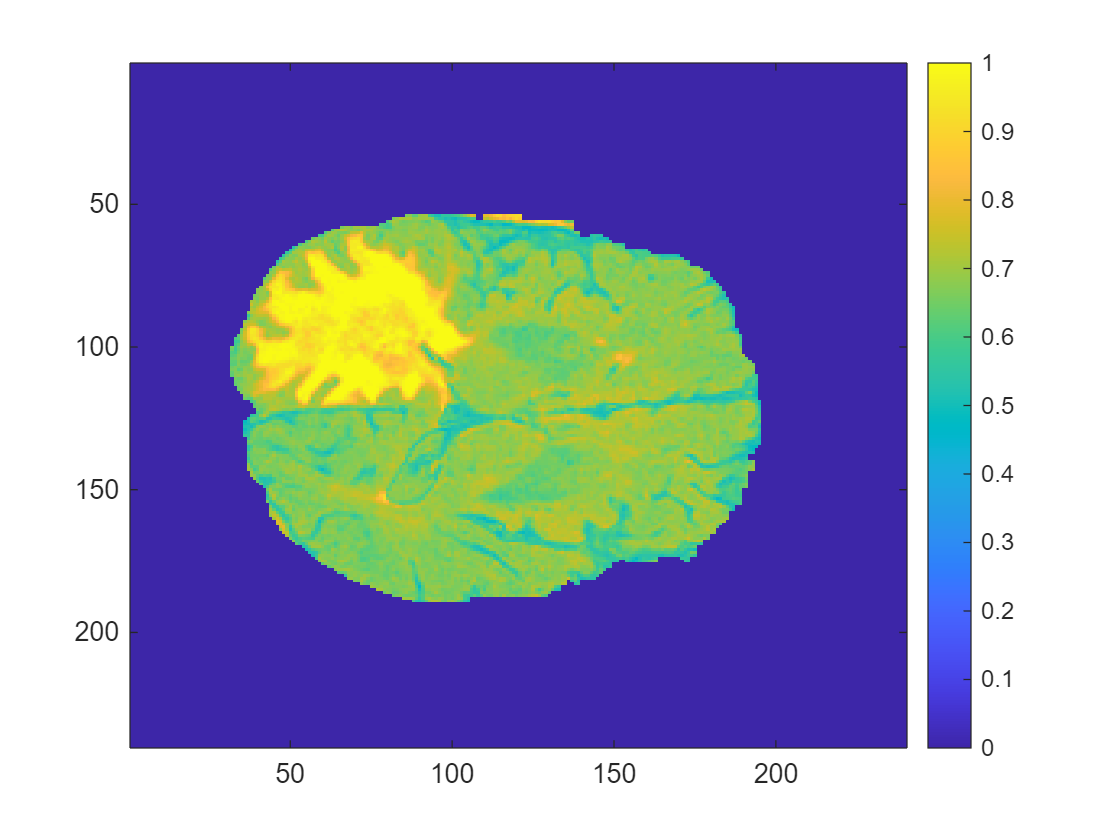

figure;
imagesc(data) % Original image
colorbar

**Defininition of the sliding window to extract features**

slidingWindow_size = [3 3];

The features extracted are normalized using the function "*normF.m*"

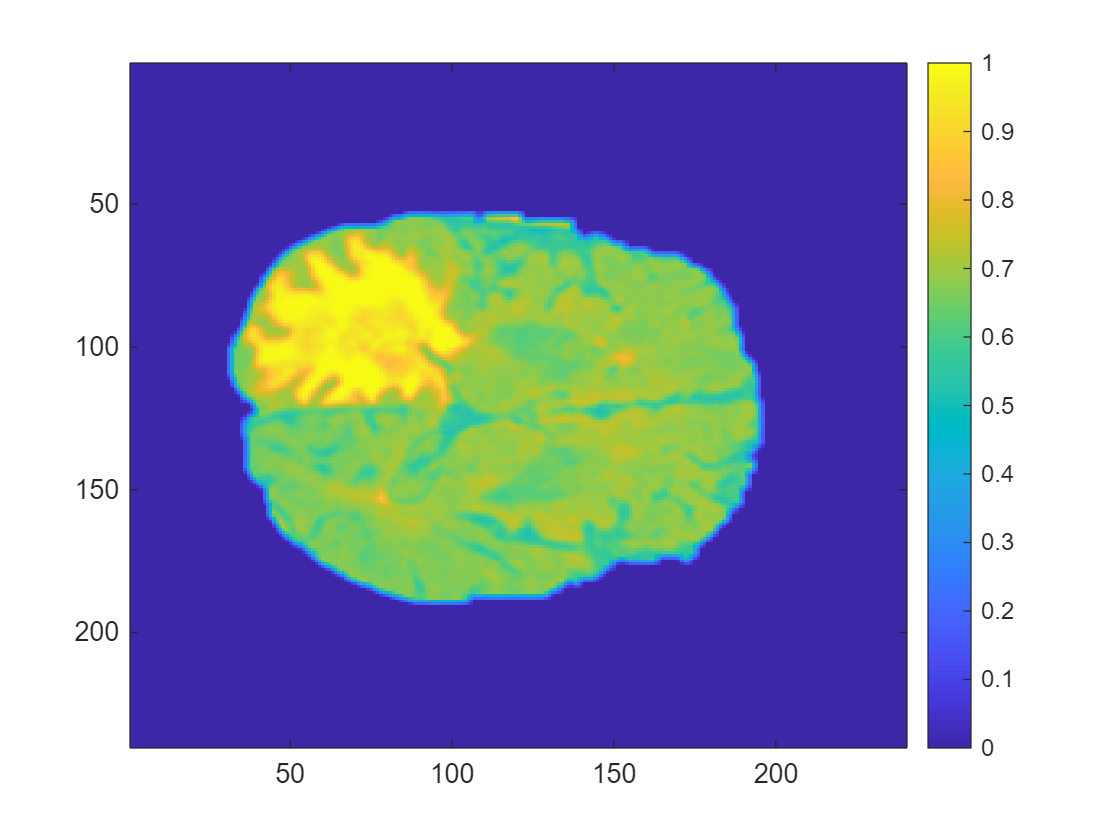

% Mean
mean_feature = colfilt(data, slidingWindow_size,'sliding',@mean);

% imagesc(mean_feature) % print the non-normalized image
normMean = normF(mean_feature); % Normalization of the values within the image

figure;
imagesc(normMean) % print the normalized image
colorbar

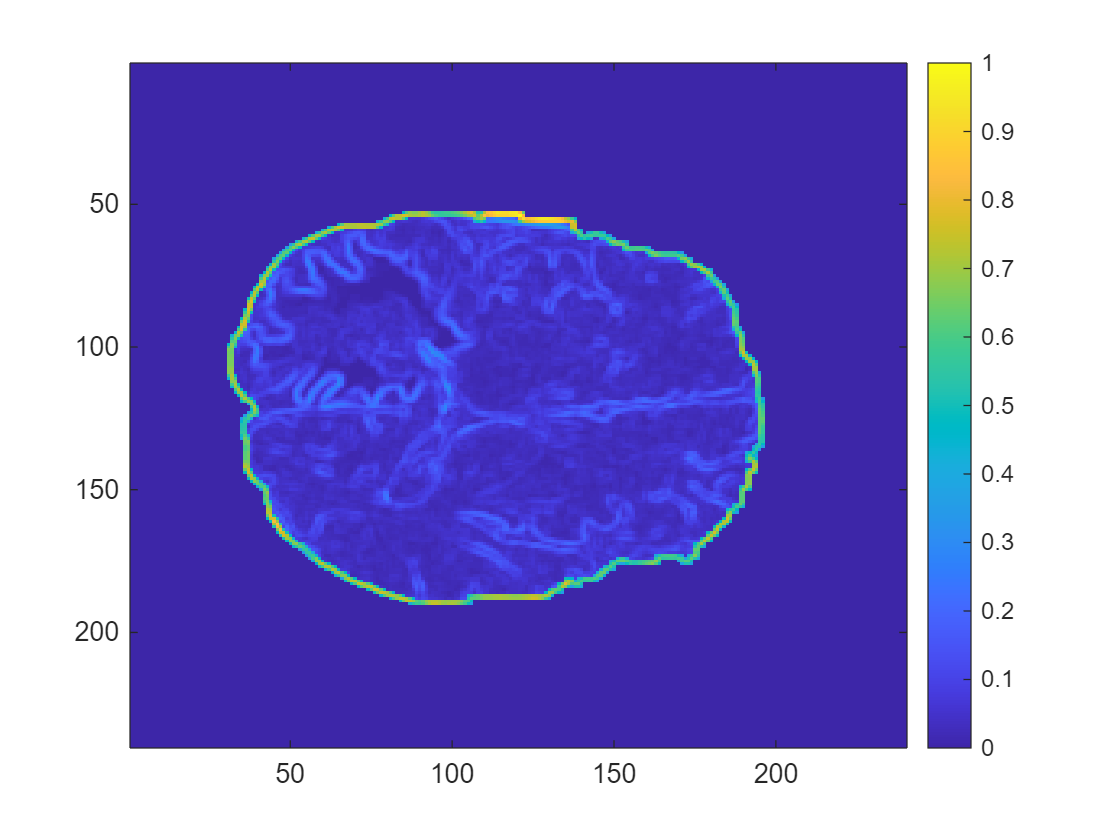

% Standard Deviation
devStandard_feature = colfilt(data, slidingWindow_size,'sliding',@std);

% imagesc(devStandard_feature) % print the non-normalized image 
normStand = normF(devStandard_feature);

figure;
imagesc(normStand) % print the normalized image
colorbar

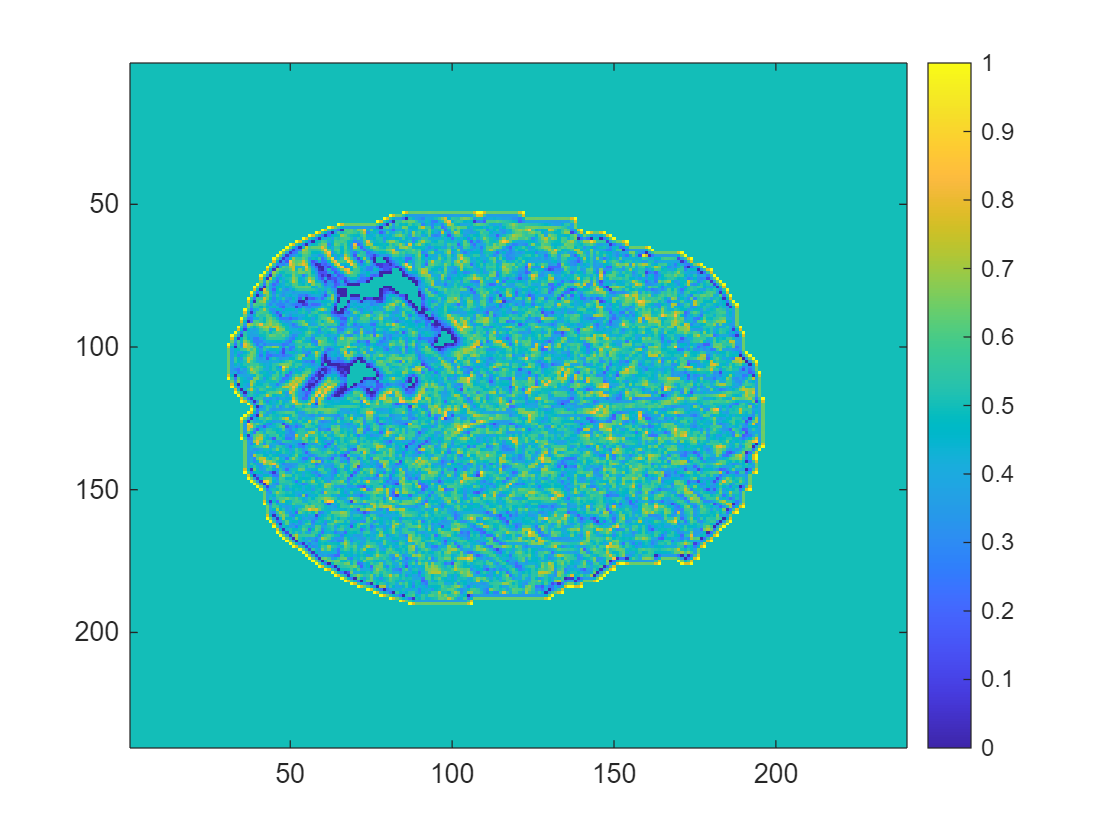

% Skewness 
skewns_feature = colfilt(data, slidingWindow_size,'sliding', @skewness);
skewns_feature(isnan(skewns_feature)) = 0; % change the nan values to 0

% imagesc(skewns_feature) % print the non-normalized image
normSkewns = normF(skewns_feature);

figure;
imagesc(normSkewns) % print normalized image
colorbar

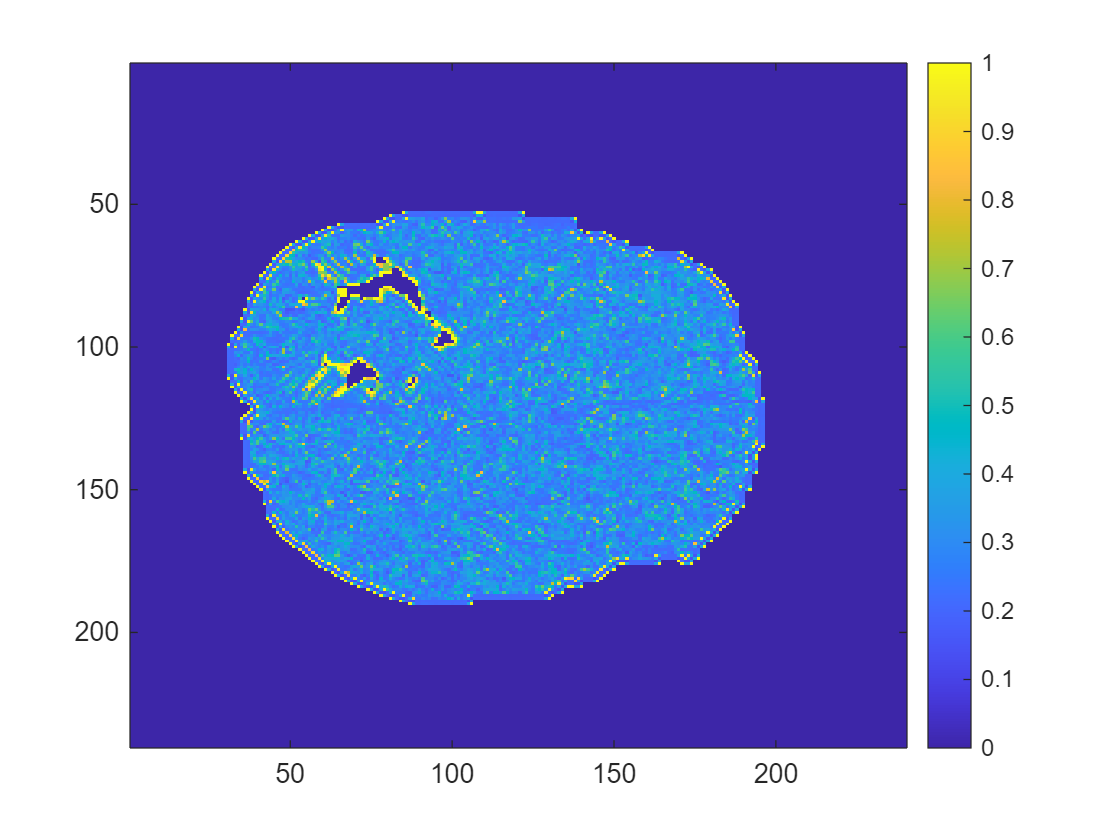

% Kurtosis
kurtss_feature = colfilt(data, slidingWindow_size,'sliding',@kurtosis);
kurtss_feature(isnan(kurtss_feature)) = 0; % change the nan values to 0

% imagesc(kurtss_feature) % print the non-normalized image
normKurtss= normF(kurtss_feature);

figure;
imagesc(normKurtss) % print normalized image
colorbar

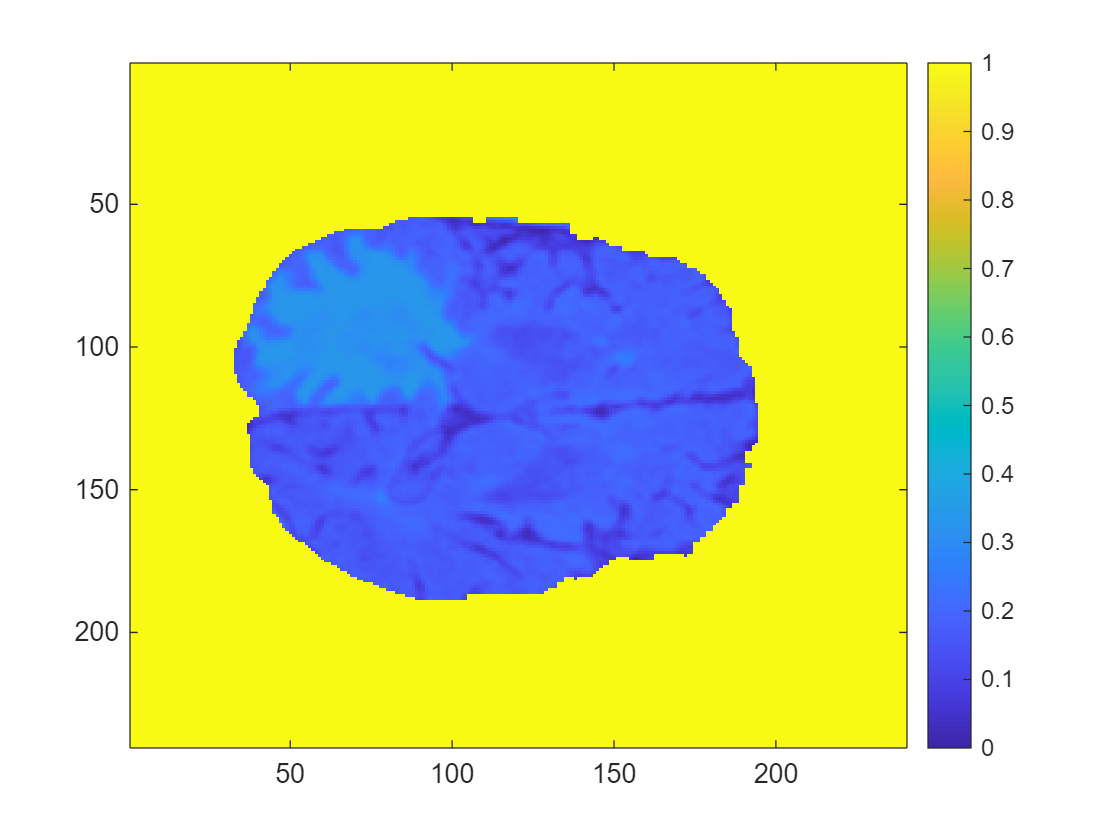

% Entropy
entropy = @(x) 0 - (sum(x - log2(x)));
entropy_feature = colfilt(data, slidingWindow_size,'sliding',entropy);
entropy_feature(entropy_feature == -Inf) = 0; % change the -Inf values to 0

% imagesc(entropy_feature) % print the non-normalized image
normEntropy = normF(entropy_feature);

figure;
imagesc(normEntropy) % print normalized image
colorbar

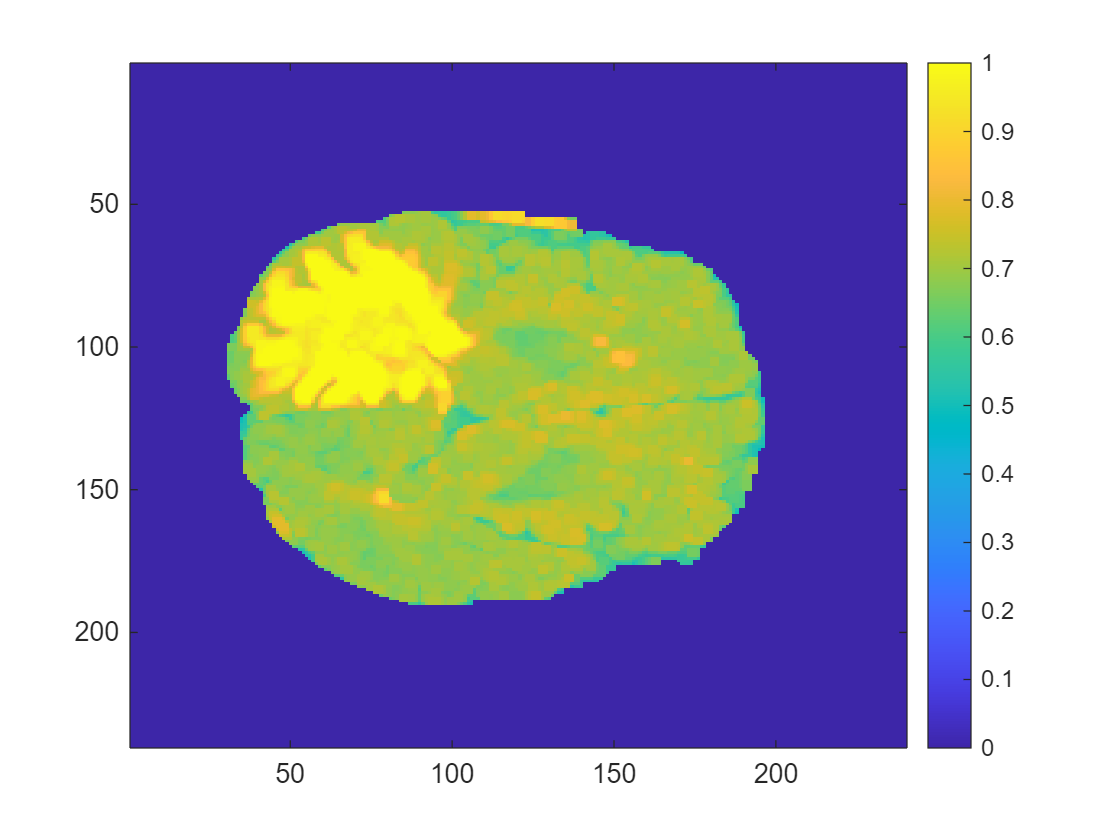

% Maximum value
max_feature = colfilt(data, slidingWindow_size,'sliding', @max);

% imagesc(max_feature) % print the non-normalized image
normMax = normF(max_feature);

figure;
imagesc(normMax) % print normalized image
colorbar

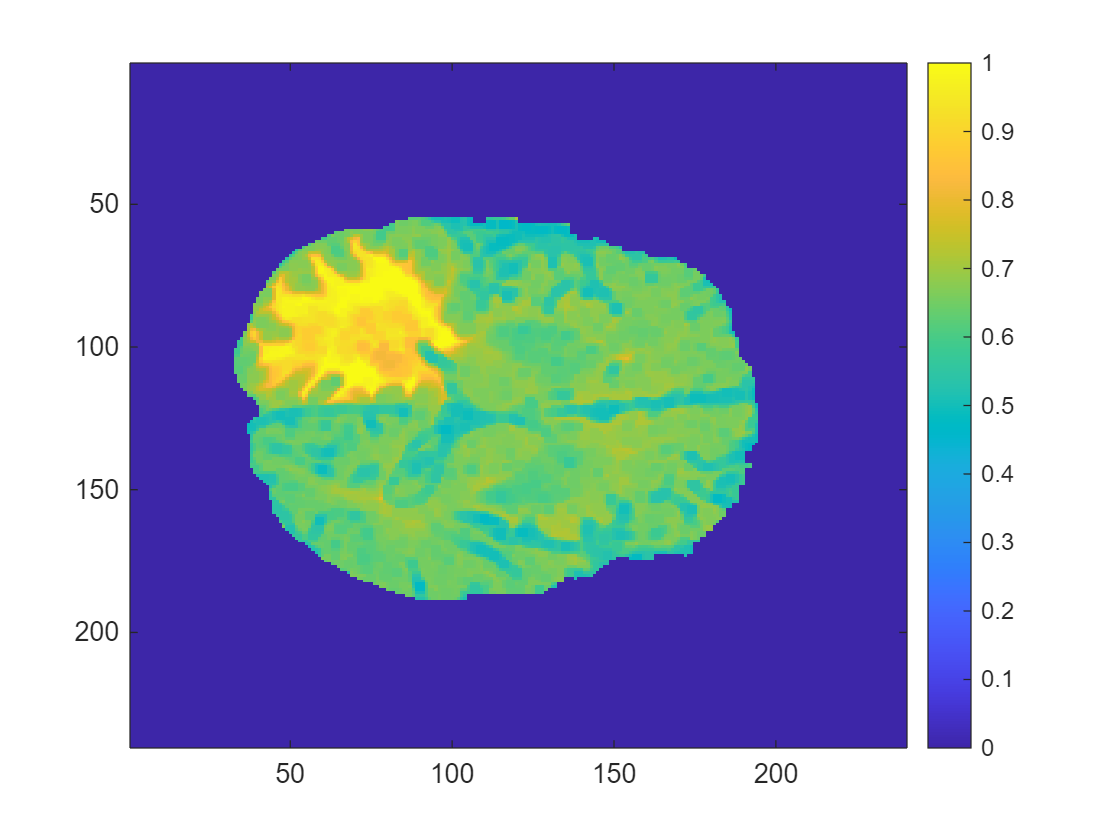

% Minimum value
min_feature = colfilt(data, slidingWindow_size,'sliding', @min);

% imagesc(min_feature) % print the non-normalized image
normMin = normF(min_feature);

figure;
imagesc(normMin) % print normalized image
colorbar

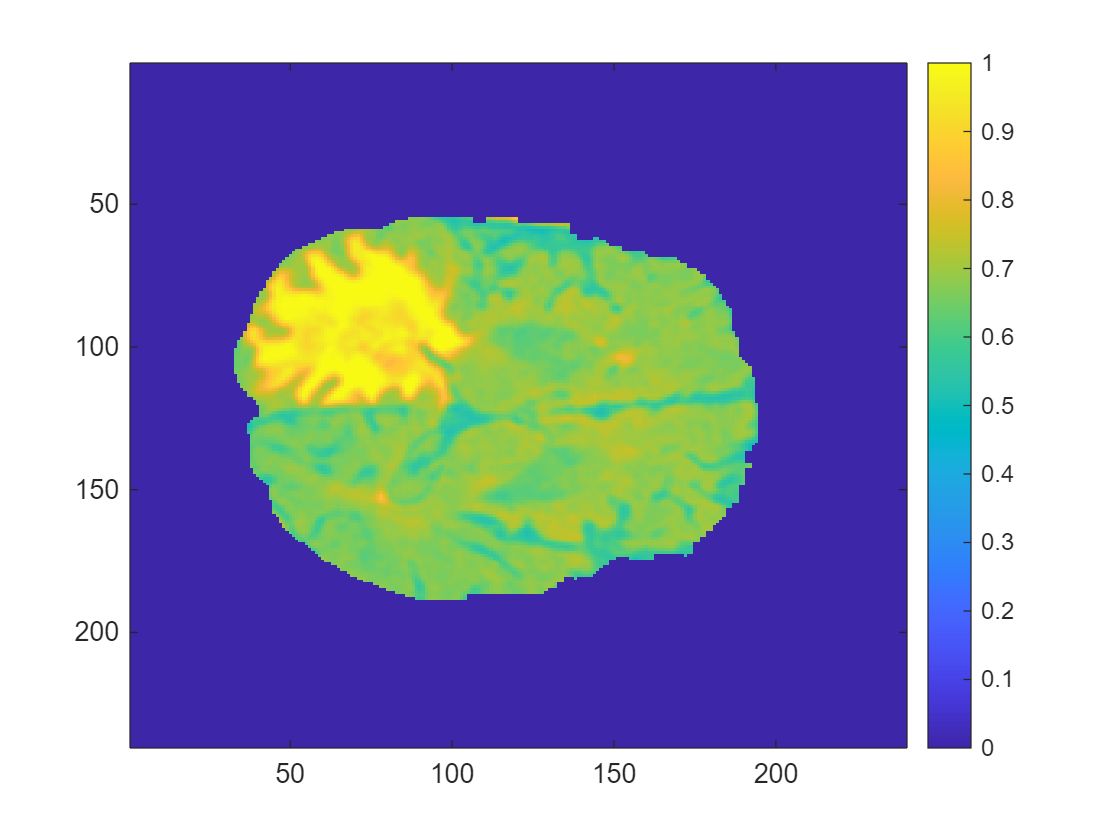

% Geometric mean
geomean_feature = colfilt(data, slidingWindow_size,'sliding', @geomean);

% imagesc(geomean_feature) % print the non-normalized image
normGeoMean = normF(geomean_feature);

figure;
imagesc(normGeoMean) % print normalized image
colorbar

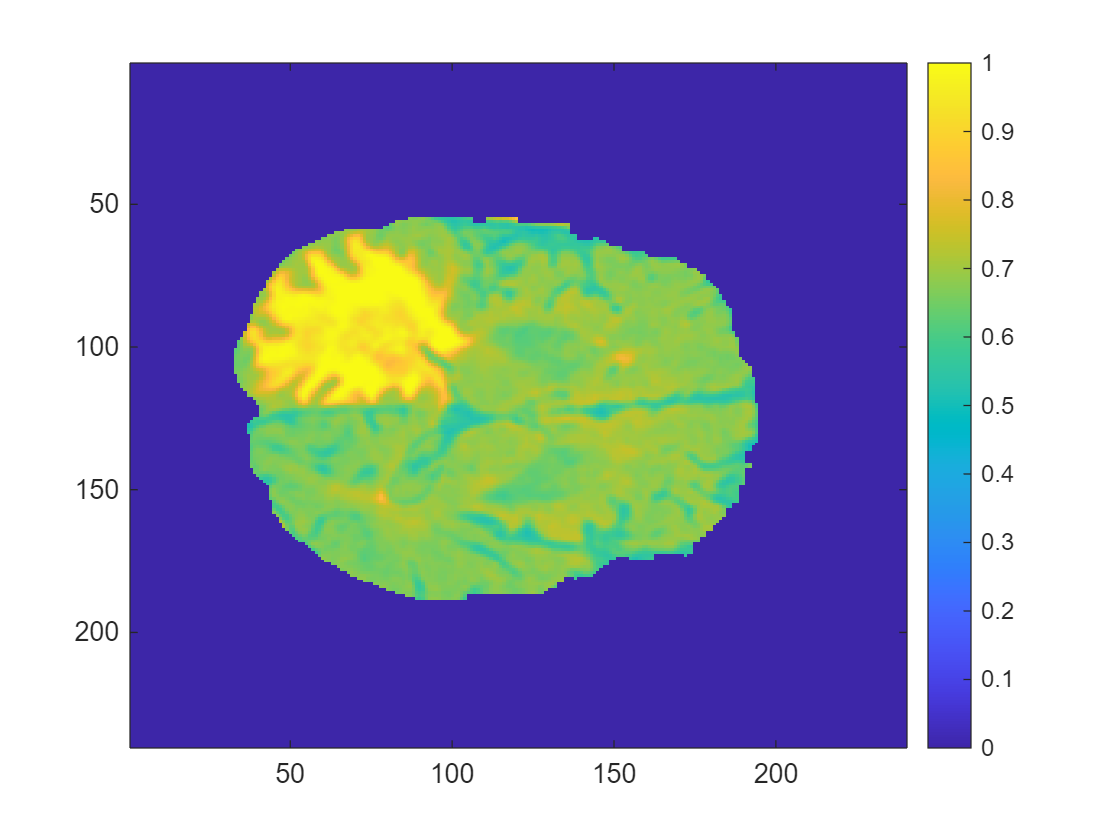

% Harmonic mean
harmmean_feature = colfilt(data, slidingWindow_size,'sliding', @harmmean);

% imagesc(harmmean_feature) % print the non-normalized image
normHarmmean = normF(harmmean_feature);

figure;
imagesc(normHarmmean) % print normalized image
colorbar

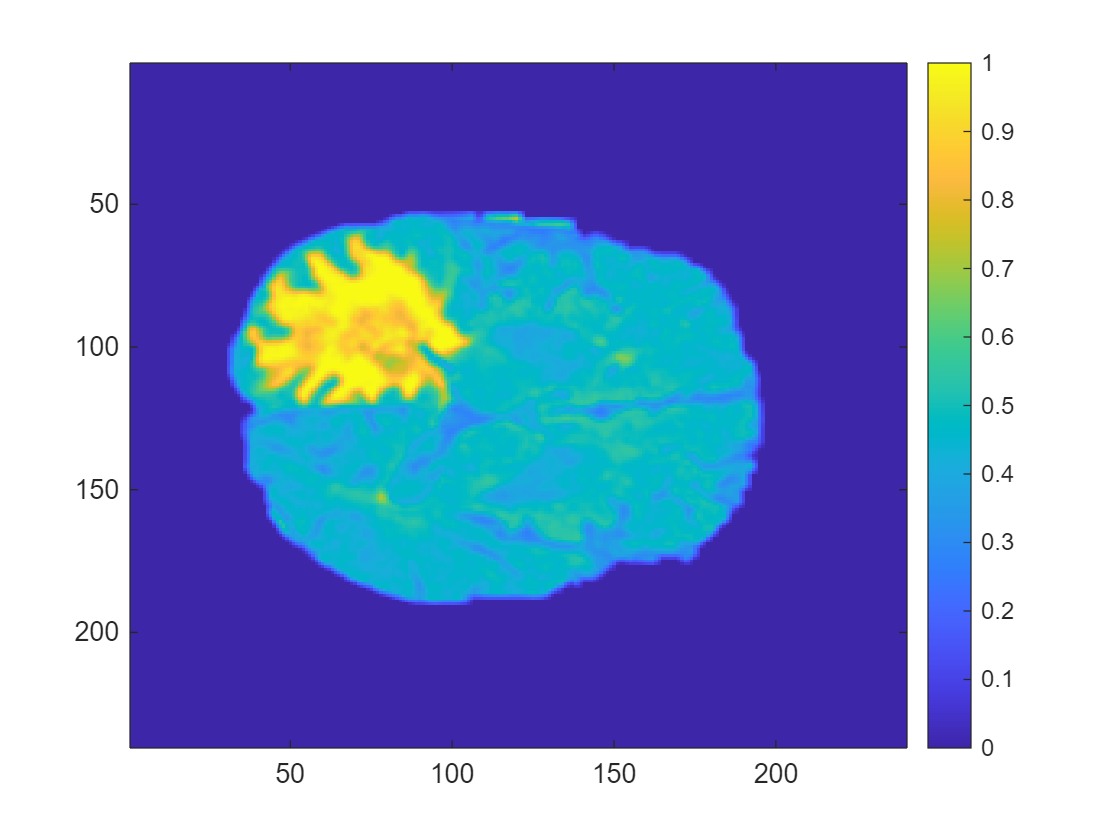

% Energy
energy_func = @(x) sum(x.^2);
energy_feature = colfilt(data, slidingWindow_size,'sliding', energy_func);

% imagesc(energy_feature) % print the non-normalized image
normEnergy = normF(energy_feature);

figure;
imagesc(normEnergy) % print normalized image
colorbar

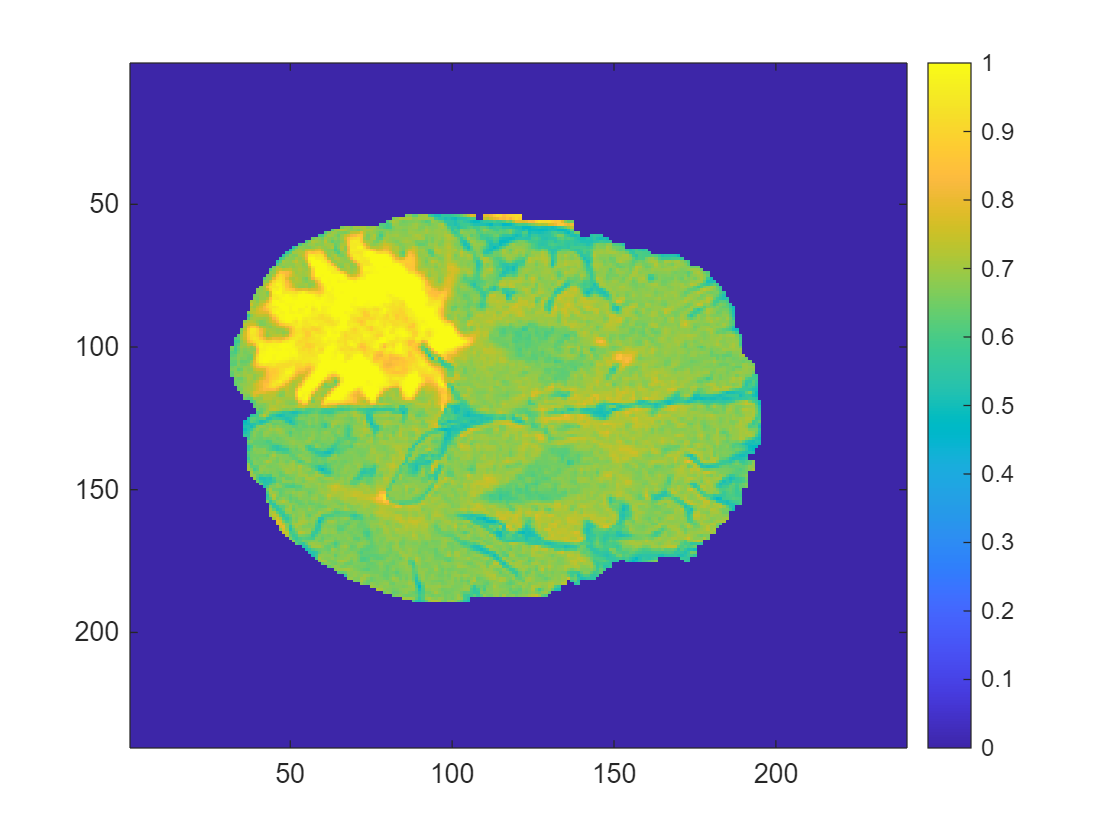

% Constrast 
contrast_feature = imadjust(data);

% imagesc(contrast_feature) % print the non-normalized image
normContrast = normF(contrast_feature);

figure;
imagesc(normContrast) % print normalized image
colorbar

**Defining the Inference system **

The definition of the inference system used to detect a tumor within the brain by exploit the linguistic variables, will be based on the following phases:

- Definition of the rules using the Mamdani-type fuzzy inference system

- Conversion to the Sugeno-type fuzzy inference system

- Evaluating which system is better between Mamdani and Sugeno (by looking at the resulting images)

The best system will then undergo optimization.

*Creating the fis with the definition of the rules*

a = mamfis("Name", "TumorSegmentation");

*Definition of the inputs*

The inputs are each feature extracted from the image

% For a pixel
a = addInput(a, [0 1], "Name", "pixel");
a = addMF(a, "pixel", "trimf", [0.75 1 1.5], "Name", "Tumor");
a = addMF(a, "pixel", "trimf", [0.1 0.5 0.8], "Name", "BrainArea");
a = addMF(a, "pixel", "trimf", [-0.5 0 0.15], "Name", "Background");

% For the mean
a = addInput(a, [0 1], "Name", "mean");
a = addMF(a, "mean", "trimf", [0.75 1 1.5], "Name", "Tumor");
a = addMF(a, "mean", "trimf", [0.1 0.5 0.8], "Name", "BrainArea");
a = addMF(a, "mean", "trimf", [-0.5 0 0.15], "Name", "Background");

% For the standard deviation
a = addInput(a, [0 1], "Name", "std");
a = addMF(a, "std", "trimf", [0.1 0.5 1.1], "Name", "BrainArea");
a = addMF(a, "std", "trimf", [-0.5 0 0.15], "Name", "Background");

% For the skewness
a = addInput(a, [0 1], "Name", "skewness");
a = addMF(a, "skewness", "trimf", [0.55 0.8 1.1], "Name", "BrainAreaRight");
a = addMF(a, "skewness", "trimf", [-0.1 0.3 0.45], "Name", "BrainAreaLeft");
a = addMF(a, "skewness", "trimf", [0.4 0.5 0.6], "Name", "Background");

% For the kurtosis
a = addInput(a, [0 1], "Name", "kurtosis");
a = addMF(a, "kurtosis", "trimf", [0.05 0.45 1.1], "Name", "BrainArea");
a = addMF(a, "kurtosis", "trimf", [-0.1 0 0.1], "Name", "Background");

% For the entropy
a = addInput(a, [0 1], "Name", "entropy");
a = addMF(a, "entropy", "trimf", [-0.1 0.2 0.35], "Name", "BrainAreaLeft");
a = addMF(a, "entropy", "trimf", [0.3 0.4 0.5], "Name", "Tumor");
a = addMF(a, "entropy", "trimf", [0.45 0.7 0.95], "Name", "BrainAreaRight");
a = addMF(a, "entropy", "trimf", [0.9 1 1.1], "Name", "Background");

% For the max
a = addInput(a, [0 1], "Name", "max");
a = addMF(a, "max", "trimf", [0.75 1 1.5], "Name", "Tumor");
a = addMF(a, "max", "trimf", [0.1 0.5 0.8], "Name", "BrainArea");
a = addMF(a, "max", "trimf", [-0.5 0 0.15], "Name", "Background");

% For the min
a = addInput(a, [0 1], "Name", "min");
a = addMF(a, "min", "trimf", [0.75 1 1.5], "Name", "Tumor");
a = addMF(a, "min", "trimf", [0.1 0.5 0.8], "Name", "BrainArea");
a = addMF(a, "min", "trimf", [-0.5 0 0.15], "Name", "Background");

% For the geometric mean
a = addInput(a, [0 1], "Name", "geom");
a = addMF(a, "geom", "trimf", [0.75 1 1.5], "Name", "Tumor");
a = addMF(a, "geom", "trimf", [0.1 0.5 0.8], "Name", "BrainArea");
a = addMF(a, "geom", "trimf", [-0.5 0 0.15], "Name", "Background");

% For the harmonic mean
a = addInput(a, [0 1], "Name", "harmm");
a = addMF(a, "harmm", "trimf", [0.75 1 1.5], "Name", "Tumor");
a = addMF(a, "harmm", "trimf", [0.1 0.5 0.8], "Name", "BrainArea");
a = addMF(a, "harmm", "trimf", [-0.5 0 0.15], "Name", "Background");

% For the energy
a = addInput(a, [0 1], "Name", "energy");
a = addMF(a, "energy", "trimf", [0.75 1 1.5], "Name", "Tumor");
a = addMF(a, "energy", "trimf", [0.1 0.5 0.8], "Name", "BrainArea");
a = addMF(a, "energy", "trimf", [-0.5 0 0.15], "Name", "Background");

% For the contrast
a = addInput(a, [0 1], "Name", "contrast");
a = addMF(a, "contrast", "trimf", [0.75 1 1.5], "Name", "Tumor");
a = addMF(a, "contrast", "trimf", [0.1 0.5 0.8], "Name", "BrainArea");
a = addMF(a, "contrast", "trimf", [-0.5 0 0.15], "Name", "Background");

*Definition of the outputs*

The output needs to determine whether there is the tumor or not

a = addOutput(a, [0 1], 'Name', 'Tumor');
a = addMF(a, 'Tumor', 'trimf', [-0.1 0.5 1], 'Name', 'No');
a = addMF(a, 'Tumor', 'trimf', [0.5 1 1.5], 'Name', 'Yes');

*Definition of the rules on the inputs and outputs*

For the rules every input was evaluated with respect to all other inputs to define whether there is the tumor

% Rules definition for when there is surely the tumor
rule1 = "If pixel is Tumor and mean is Tumor, then Tumor is Yes";
rule2 = "If pixel is Tumor and std is BrainArea, then Tumor is Yes";
rule5 = "If pixel is Tumor and entropy is Tumor, then Tumor is Yes";
rule6 = "If pixel is Tumor and max is Tumor, then Tumor is Yes";
rule8 = "If pixel is Tumor and geom is Tumor, then Tumor is Yes";
rule9 = "If pixel is Tumor and harmm is Tumor, then Tumor is Yes";
rule10 = "If pixel is Tumor and energy is Tumor, then Tumor is Yes";
rule11 = "If pixel is Tumor and contrast is Tumor, then Tumor is Yes";
rule40 = "If mean is Tumor and kurtosis is BrainArea, then Tumor is Yes";
rule41 = "If mean is Tumor and entropy is Tumor, then Tumor is Yes";
rule42 = "If mean is Tumor and max is Tumor, then Tumor is Yes";
rule44 = "If mean is Tumor and geom is Tumor, then Tumor is Yes";
rule45 = "If mean is Tumor and harmm is Tumor, then Tumor is Yes";
rule46 = "If mean is Tumor and energy is Tumor, then Tumor is Yes";
rule47 = "If mean is Tumor and contrast is Tumor, then Tumor is Yes";
rule49 = "If entropy is Tumor and skewness is BrainAreaRight, then Tumor is Yes";
rule52 = "If entropy is Tumor and max is Tumor, then Tumor is Yes";
rule53 = "If entropy is Tumor and min is Tumor, then Tumor is Yes";
rule54 = "If entropy is Tumor and geom is Tumor, then Tumor is Yes";
rule55 = "If entropy is Tumor and harmm is Tumor, then Tumor is Yes";
rule56 = "If entropy is Tumor and energy is Tumor, then Tumor is Yes";
rule57 = "If entropy is Tumor and contrast is Tumor, then Tumor is Yes";
rule62 = "If max is Tumor and min is Tumor, then Tumor is Yes";
rule63 = "If max is Tumor and geom is Tumor, then Tumor is Yes";
rule64 = "If max is Tumor and harmm is Tumor, then Tumor is Yes";
rule65 = "If max is Tumor and energy is Tumor, then Tumor is Yes";
rule66 = "If max is Tumor and contrast is Tumor, then Tumor is Yes";
rule71 = "If min is Tumor and geom is Tumor, then Tumor is Yes";
rule72 = "If min is Tumor and harmm is Tumor, then Tumor is Yes";
rule73 = "If min is Tumor and energy is Tumor, then Tumor is Yes";
rule74 = "If min is Tumor and contrast is Tumor, then Tumor is Yes";
rule79 = "If geom is Tumor and harmm is Tumor, then Tumor is Yes";
rule80 = "If geom is Tumor and energy is Tumor, then Tumor is Yes";
rule81 = "If geom is Tumor and contrast is Tumor, then Tumor is Yes";
rule85 = "If harmm is Tumor and energy is Tumor, then Tumor is Yes";
rule86 = "If harmm is Tumor and contrast is Tumor, then Tumor is Yes";
rule90 = "If energy is Tumor and contrast is Tumor, then Tumor is Yes";

% Rules definition for when it is just a brain region
rule12 = "If pixel is BrainArea and mean is BrainArea, then Tumor is No";
rule13 = "If pixel is BrainArea and std is BrainArea, then Tumor is No";
rule14 = "If pixel is BrainArea and skewness is BrainAreaRight, then Tumor is No";
rule35 = "If pixel is BrainArea and skewness is BrainAreaLeft, then Tumor is No";
rule15 = "If pixel is BrainArea and kurtosis is BrainArea, then Tumor is No";
rule16 = "If pixel is BrainArea and entropy is BrainAreaRight, then Tumor is No";
rule36 = "If pixel is BrainArea and entropy is BrainAreaLeft, then Tumor is No";
rule17 = "If pixel is BrainArea and max is BrainArea, then Tumor is No";
rule18 = "If pixel is BrainArea and min is BrainArea, then Tumor is No";
rule19 = "If pixel is BrainArea and geom is BrainArea, then Tumor is No";
rule20 = "If pixel is BrainArea and harmm is BrainArea, then Tumor is No";
rule21 = "If pixel is BrainArea and energy is BrainArea, then Tumor is No";
rule22 = "If pixel is BrainArea and contrast is BrainArea, then Tumor is No";
rule97 = "If mean is BrainArea and std is BrainArea, then Tumor is No";
rule98 = "If mean is BrainArea and skewness is BrainAreaRight, then Tumor is No";
rule99 = "If mean is BrainArea and skewness is BrainAreaLeft, then Tumor is No";
rule100 = "If mean is BrainArea and kurtosis is BrainArea, then Tumor is No";
rule101 = "If mean is BrainArea and entropy is BrainAreaRight, then Tumor is No";
rule102 = "If mean is BrainArea and entropy is BrainAreaLeft, then Tumor is No";
rule107 = "If mean is BrainArea and energy is BrainArea, then Tumor is No";
rule108 = "If mean is BrainArea and contrast is BrainArea, then Tumor is No";
rule109 = "If std is BrainArea and skewness is BrainAreaRight, then Tumor is No";
rule110= "If std is BrainArea and skewness is BrainAreaLeft, then Tumor is No";
rule111 = "If std is BrainArea and kurtosis is BrainArea, then Tumor is No";
rule112 = "If std is BrainArea and entropy is BrainAreaRight, then Tumor is No";
rule113 = "If std is BrainArea and entropy is BrainAreaLeft, then Tumor is No";
rule118 = "If std is BrainArea and energy is BrainArea, then Tumor is No";
rule119 = "If std is BrainArea and contrast is BrainArea, then Tumor is No";
rule120 = "If skewness is not Background and kurtosis is BrainArea, then Tumor is No";
rule121 = "If skewness is not Background and entropy is BrainAreaRight, then Tumor is No";
rule123 = "If skewness is not Background and entropy is BrainAreaLeft, then Tumor is No";
rule124 = "If skewness is not Background and max is BrainArea, then Tumor is No";
rule126 = "If skewness is not Background and geom is BrainArea, then Tumor is No";
rule128 = "If skewness is not Background and energy is BrainArea, then Tumor is No";
rule129 = "If skewness is not Background and contrast is BrainArea, then Tumor is No";
rule130 = "If kurtosis is BrainArea and entropy is BrainAreaRight, then Tumor is No";
rule131 = "If kurtosis is BrainArea and entropy is BrainAreaLeft, then Tumor is No";
rule132 = "If kurtosis is BrainArea and max is BrainArea, then Tumor is No";
rule136 = "If kurtosis is BrainArea and energy is BrainArea, then Tumor is No";
rule137 = "If kurtosis is BrainArea and contrast is BrainArea, then Tumor is No";
rule138 = "If entropy is BrainAreaRight and max is BrainArea, then Tumor is No";
rule140 = "If entropy is BrainAreaRight and geom is BrainArea, then Tumor is No";
rule142 = "If entropy is BrainAreaRight and energy is BrainArea, then Tumor is No";
rule143 = "If entropy is BrainAreaRight and contrast is BrainArea, then Tumor is No";
rule145 = "If entropy is BrainAreaLeft and min is BrainArea, then Tumor is No";
rule147 = "If entropy is BrainAreaLeft and harmm is BrainArea, then Tumor is No";
rule148 = "If entropy is BrainAreaLeft and energy is BrainArea, then Tumor is No";
rule149 = "If entropy is BrainAreaLeft and contrast is BrainArea, then Tumor is No";
rule153 = "If max is BrainArea and energy is BrainArea, then Tumor is No";
rule154 = "If max is BrainArea and contrast is BrainArea, then Tumor is No";
rule157 = "If min is BrainArea and energy is BrainArea, then Tumor is No";
rule158 = "If min is BrainArea and contrast is BrainArea, then Tumor is No";

% Rules definition for when it is just a background region
rule23 = "If pixel is Background and mean is Background, then Tumor is No";
rule24 = "If pixel is Background and std is Background, then Tumor is No";
rule25 = "If pixel is Background and skewness is Background, then Tumor is No";
rule26 = "If pixel is Background and kurtosis is Background, then Tumor is No";
rule27 = "If pixel is Background and entropy is Background, then Tumor is No";
rule28 = "If pixel is Background and max is Background, then Tumor is No";
rule29 = "If pixel is Background and min is Background, then Tumor is No";
rule30 = "If pixel is Background and geom is Background, then Tumor is No";
rule31 = "If pixel is Background and harmm is Background, then Tumor is No";
rule32 = "If pixel is Background and energy is Background, then Tumor is No";
rule33 = "If pixel is Background and contrast is Background, then Tumor is No";
rule165 = "If mean is Background and std is Background, then Tumor is No";
rule166 = "If mean is Background and skewness is Background, then Tumor is No";
rule167 = "If mean is Background and kurtosis is Background, then Tumor is No";
rule168 = "If mean is Background and entropy is Background, then Tumor is No";
rule182 = "If mean is Background and energy is Background, then Tumor is No";
rule183 = "If mean is Background and contrast is Background, then Tumor is No";
rule208 = "If entropy is Background and max is Background, then Tumor is No";
rule209 = "If entropy is Background and min is Background, then Tumor is No";
rule210 = "If entropy is Background and geom is Background, then Tumor is No";
rule211 = "If entropy is Background and harmm is Background, then Tumor is No";
rule212 = "If entropy is Background and energy is Background, then Tumor is No";
rule213 = "If entropy is Background and contrast is Background, then Tumor is No";
rule214 = "If max is Background and min is Background, then Tumor is No";
rule215 = "If max is Background and geom is Background, then Tumor is No";
rule216 = "If max is Background and harmm is Background, then Tumor is No";
rule217 = "If max is Background and energy is Background, then Tumor is No";
rule218 = "If max is Background and contrast is Background, then Tumor is No";
rule219 = "If min is Background and geom is Background, then Tumor is No";
rule220 = "If min is Background and harmm is Background, then Tumor is No";
rule221 = "If min is Background and energy is Background, then Tumor is No";
rule222 = "If min is Background and contrast is Background, then Tumor is No";
rule223 = "If geom is Background and harmm is Background, then Tumor is No";
rule224 = "If geom is Background and energy is Background, then Tumor is No";
rule225 = "If geom is Background and contrast is Background, then Tumor is No";
rule226 = "If harmm is Background and energy is Background, then Tumor is No";
rule227 = "If harmm is Background and contrast is Background, then Tumor is No";
rule228 = "If energy is Background and contrast is Background, then Tumor is No";

% Adding the rules to the FIS
ruleList = [
    rule1
    rule2
    rule5
    rule6
    rule8
    rule9
    rule10
    rule11
    rule12
    rule13
    rule14
    rule15
    rule16
    rule17
    rule18
    rule19
    rule20
    rule21
    rule22
    rule23
    rule24
    rule25
    rule26
    rule27
    rule28
    rule29
    rule30
    rule31
    rule32
    rule33
    rule35
    rule36
    rule40
    rule41
    rule42
    rule44
    rule45
    rule46
    rule47
    rule49
    rule52
    rule53
    rule54
    rule55
    rule56
    rule57
    rule62
    rule63
    rule64
    rule65
    rule66
    rule71
    rule72
    rule73
    rule74
    rule79
    rule80
    rule81
    rule85
    rule86 
    rule90
    rule97
    rule98
    rule99
    rule100
    rule101
    rule102
    rule107
    rule108
    rule109
    rule110
    rule111
    rule112
    rule113
    rule118
    rule119
    rule120
    rule121
    rule123
    rule124
    rule126
    rule128
    rule129
    rule130
    rule131
    rule132
    rule136
    rule137
    rule138
    rule140
    rule142
    rule143
    rule145
    rule147
    rule148
    rule149
    rule153
    rule154
    rule157
    rule158
    rule165
    rule166
    rule167
    rule168
    rule182
    rule183 
    rule208
    rule209
    rule210
    rule211
    rule212
    rule213
    rule214
    rule215
    rule216
    rule217
    rule218
    rule219
    rule220
    rule221
    rule222
    rule223
    rule224
    rule225
    rule226
    rule227
    rule228
];

a = addRule(a, ruleList);

% Printing the rules defined
a.Rules

ans =   1×127 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                                     Description                           
           ________________________________________________________________

    1      "pixel==Tumor & mean==Tumor => Tumor=Yes (1)"                   
    2      "pixel==Tumor & std==BrainArea => Tumor=Yes (1)"                
    3      "pixel==Tumor & entropy==Tumor => Tumor=Yes (1)"                
    4      "pixel==Tumor & max==Tumor => Tumor=Yes (1)"                    
    5      "pixel==Tumor & geom==Tumor => Tumor=Yes (1)"                   
    6      "pixel==Tumor & harmm==Tumor => Tumor=Yes (1)"                  
    7      "pixel==Tumor & energy==Tumor 

*Visualizing the Mamdani Fuzzy Inference System created*

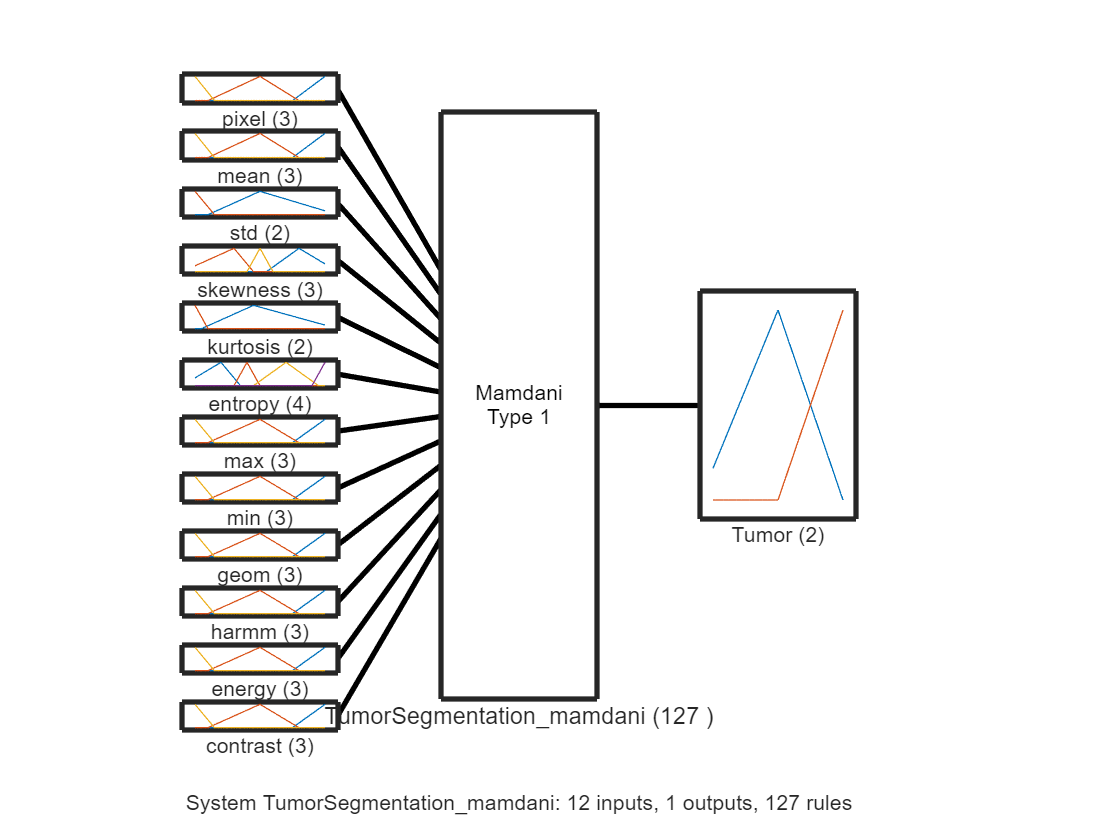

% Saving the FIS
a.Name = "TumorSegmentation_mamdani";

% writeFIS(a, a.Name);
% commented because otherwise it is saved everytime I run the code

% Visualizing the Mamdani Inference System
plotfis(a)

*Evaluating the Mamdani inference system*

% Get the dimensions of the image
dimY = size(data,1);
dimX = size(data,2);

% Defining the inputs of the FIS (the features extracted previously)
inputs_mam = [ ... 
    data(:), ...
    normMean(:), ...
    normStand(:), ...
    normSkewns(:), ...
    normKurtss(:), ...
    normEntropy(:), ...
    normMax(:), ...
    normMin(:), ...
    normGeoMean(:), ...
    normHarmmean(:), ...
    normEnergy(:), ...
    normContrast(:), ...
];

% Evaluating the pixels using the Mamdani FIS
tumorScores_mam = evalfis(a, inputs_mam);  % size: [numPixels x 1]

% Exploring the values of the scores
minScore_mam = min(tumorScores_mam, [], "all");
maxScore_mam = max(tumorScores_mam, [], "all");

% Threshold definition to distinguish whether there is the tumor
tumorMask_mam = reshape(tumorScores_mam > 0.55, dimY, dimX);
% Reshaping of the results to have the same size as the original image

Printing the rusults of the Mamdani 

% Printing the image with only the tumor
figure;
imagesc(tumorMask_mam);
title("Mamdani FIS result");
colorbar;

*Conversion of the Mamdani inference system to a Sugeno inference system*

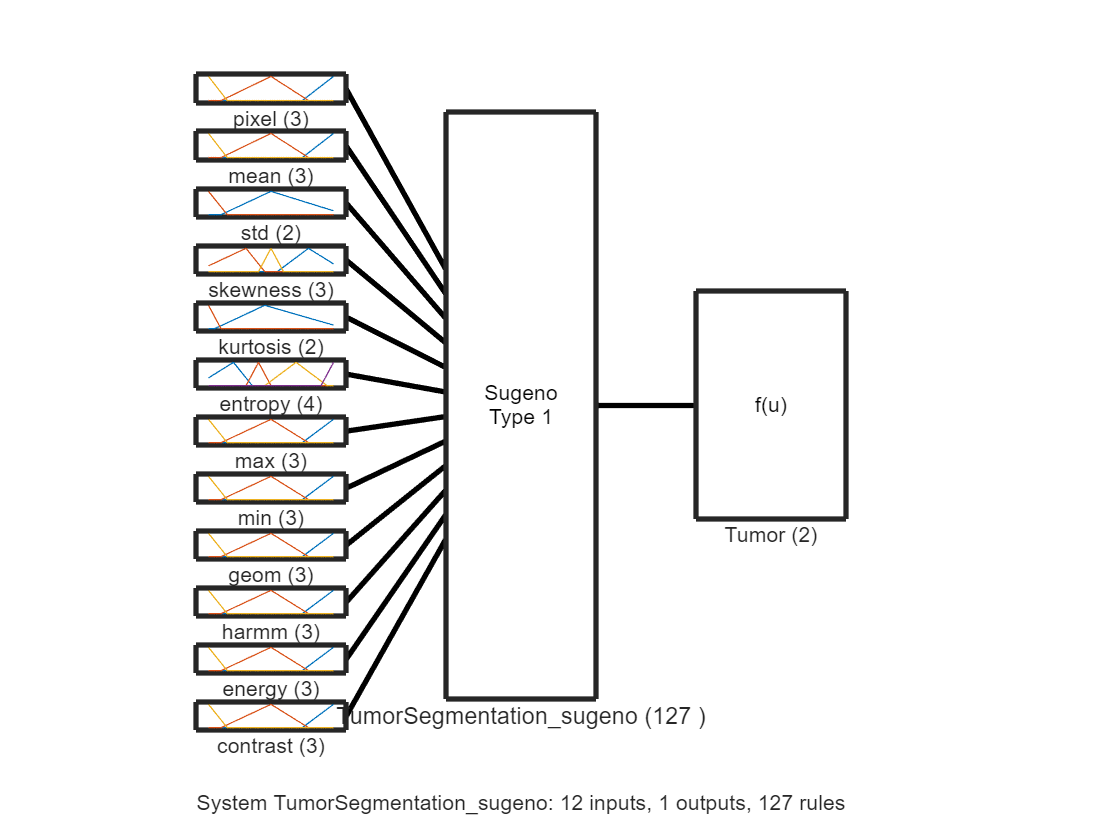

sug_fis = convertToSugeno(a);
% Saving the FIS
sug_fis.Name = "TumorSegmentation_sugeno";

% writeFIS(sug_fis, sug_fis.Name);
% commented because otherwise it is saved everytime I run the code

% Visualizing the Sugeno Inference System
plotfis(sug_fis)

*Evaluating the Sugeno inference system*

% Defining the inputs of the FIS (the features extracted previously)
inputs_sug = [ ... 
    data(:), ...
    normMean(:), ...
    normStand(:), ...
    normSkewns(:), ...
    normKurtss(:), ...
    normEntropy(:), ...
    normMax(:), ...
    normMin(:), ...
    normGeoMean(:), ...
    normHarmmean(:), ...
    normEnergy(:), ...
    normContrast(:), ...
];

% Evaluating the pixels using the Sugeno FIS
tumorScores_sug = evalfis(sug_fis, inputs_sug);  % size: [numPixels x 1]

% Exploring the values of the scores
minScore_sug = min(tumorScores_sug, [], "all");
maxScore_sug = max(tumorScores_sug, [], "all");

% Threshold definition to distinguish whether there is the tumor
tumorMask_sug = reshape(tumorScores_sug > 0.7, dimY, dimX);
% Reshaping of the results to have the same size as the original image

Printing the results of the Sugeno FIS

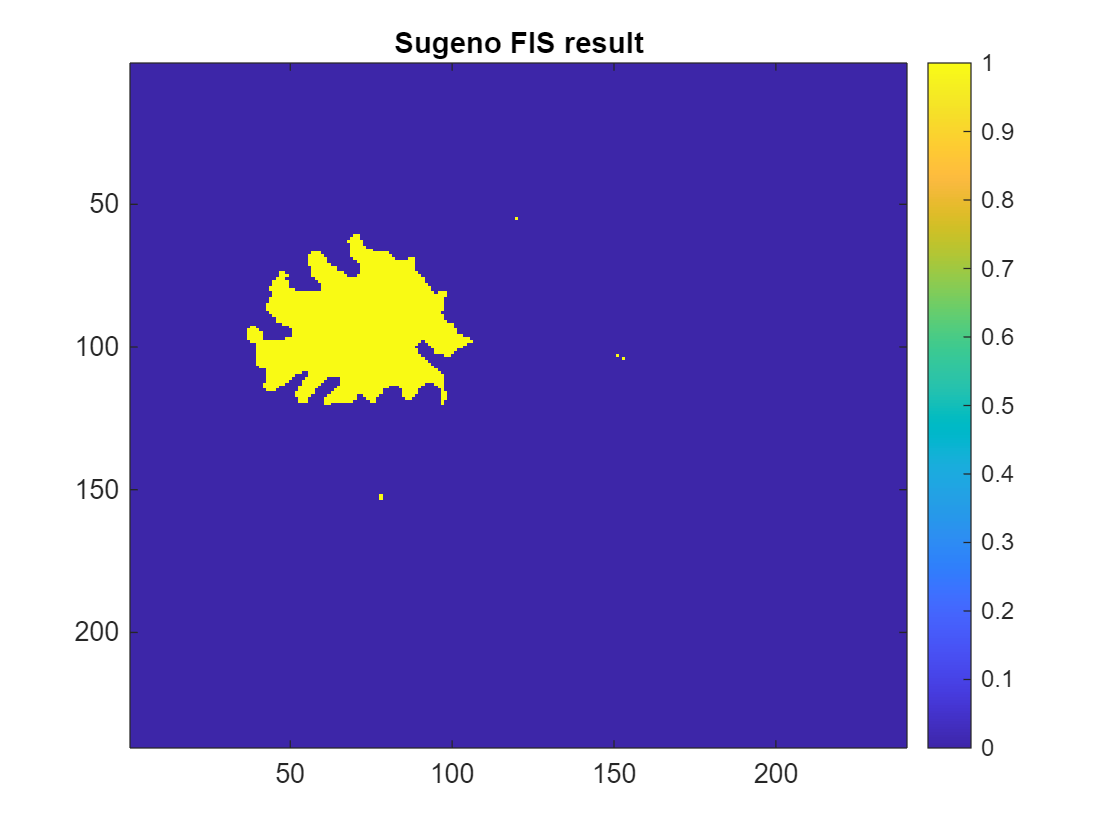

% Printing the image with only the tumor
figure;
imagesc(tumorMask_sug);
title("Sugeno FIS result");
colorbar;

### Phase 2: Genetic Algorithm for Rule Weights Tuning

During this second phase of the project, a genetic algorithm that identifies the best rule weights combinations for the implemented Mamdani and Sugeno FIS for tumor segmentation will be created.

For the second phase of the project the Sugeno FIS will be used, since in the previous printed images it is a clearer image.

*Copying the Sugeno FIS for the optimized FIS*

% Get the Sugeno FIS that will be optimized
optimized_fis = readfis("TumorSegmentation_sugeno.fis")

optimized_fis =   sugfis with properties:

                       Name: "TumorSegmentation_sugeno"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×12 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×127 fisrule]

	See 'getTunableSettings' method for parameter optimization.


% Change the name of the FIS
optimized_fis.Name = "TumorSegmentation_optimization";

*Initialization with a random set of rule weights*

We have generalized the method to create random weight within a vector in the function "*generateVectWeights.m*"

% Get the number of rules in the FIS
numRules = numel(optimized_fis.Rules);

% Defining the initial population with vectors of rules
weight1 = generateVectWeights(numRules)

weight1 =     0.7248    0.3881    0.2244    0.4121    0.6708    0.3056    0.3485    0.7282    0.7664    0.0995    0.9445    0.6405    0.8126    0.2644    0.5011    0.1588    0.3020    0.3342    0.4512    0.2832    0.4579    0.3162    0.3065    0.7310    0.4553    0.7630    0.3387    0.3168    0.7196    0.9767    0.6611    0.8350    0.9840    0.5306    0.6956    0.2685    0.5735    0.4938    0.7402    0.5385    0.9077    0.4643    0.7455    0.6299    0.7757    0.2055    0.6290    0.7117    0.0531    0.7850


weight2 = generateVectWeights(numRules)

weight2 =     0.8404    0.1215    0.5928    0.5277    0.0345    0.8507    0.0106    0.1068    0.4599    0.4216    0.9652    0.6472    0.5781    0.7827    0.5313    0.7921    0.7597    0.5910    0.7312    0.3247    0.3786    0.6689    0.7741    0.1298    0.3355    0.0415    0.2574    0.9419    0.6799    0.4586    0.4086    0.2472    0.1073    0.5334    0.8743    0.8230    0.2835    0.8861    0.4441    0.9705    0.4074    0.6673    0.4446    0.2575    0.0718    0.7492    0.0489    0.6308    0.3553    0.1111


weight3 = generateVectWeights(numRules)

weight3 =     0.2215    0.4152    0.0827    0.5365    0.9097    0.6191    0.8262    0.7738    0.4713    0.9151    0.7788    0.2718    0.5790    0.3002    0.7281    0.5575    0.9129    0.7542    0.3465    0.5427    0.8722    0.2763    0.5495    0.2977    0.8508    0.6621    0.0149    0.6759    0.7923    0.3130    0.1904    0.0590    0.7782    0.1741    0.2597    0.0799    0.2185    0.1863    0.0124    0.8952    0.8232    0.1038    0.9002    0.6326    0.1957    0.8081    0.9533    0.7755    0.5744    0.4871


weight4 = generateVectWeights(numRules)

weight4 =     0.5978    0.9244    0.2207    0.7594    0.5555    0.3337    0.5581    0.9502    0.1161    0.5895    0.5108    0.7992    0.9672    0.3799    0.5726    0.9686    0.6186    0.1024    0.8407    0.5667    0.4080    0.0475    0.6061    0.0742    0.5202    0.8018    0.5706    0.2423    0.4150    0.0074    0.0572    0.2592    0.5254    0.2391    0.2215    0.6392    0.6176    0.3970    0.0286    0.8637    0.2310    0.6686    0.4098    0.8125    0.8654    0.0641    0.3994    0.2685    0.6615    0.2516


weight5 = generateVectWeights(numRules)

weight5 =     0.5723    0.9634    0.5951    0.8566    0.0991    0.8439    0.8440    0.9472    0.9442    0.9901    0.0884    0.7557    0.0536    0.9493    0.0253    0.2806    0.3351    0.1375    0.5893    0.0429    0.4921    0.8383    0.5156    0.1105    0.2830    0.9540    0.3787    0.6476    0.9107    0.5805    0.7478    0.1964    0.1934    0.9819    0.4438    0.7611    0.3700    0.2806    0.2654    0.6149    0.0413    0.5568    0.4926    0.3464    0.7853    0.5105    0.2252    0.0938    0.1670    0.2640


% matrix where each column is a weight vector
population = [weight1, weight2, weight3, weight4, weight5];

*Fitness function*

The fitness function will be used to assess each combination's performance by comparing the resulting FIS segmentation to a provided gold-standard tumor mask. The fitness function will be based on the difference with the golden standard, since we have to minimize the error between the FIS prediction and the gold-standard.

The fitness function was defined in "*FitnessFunc.m*"

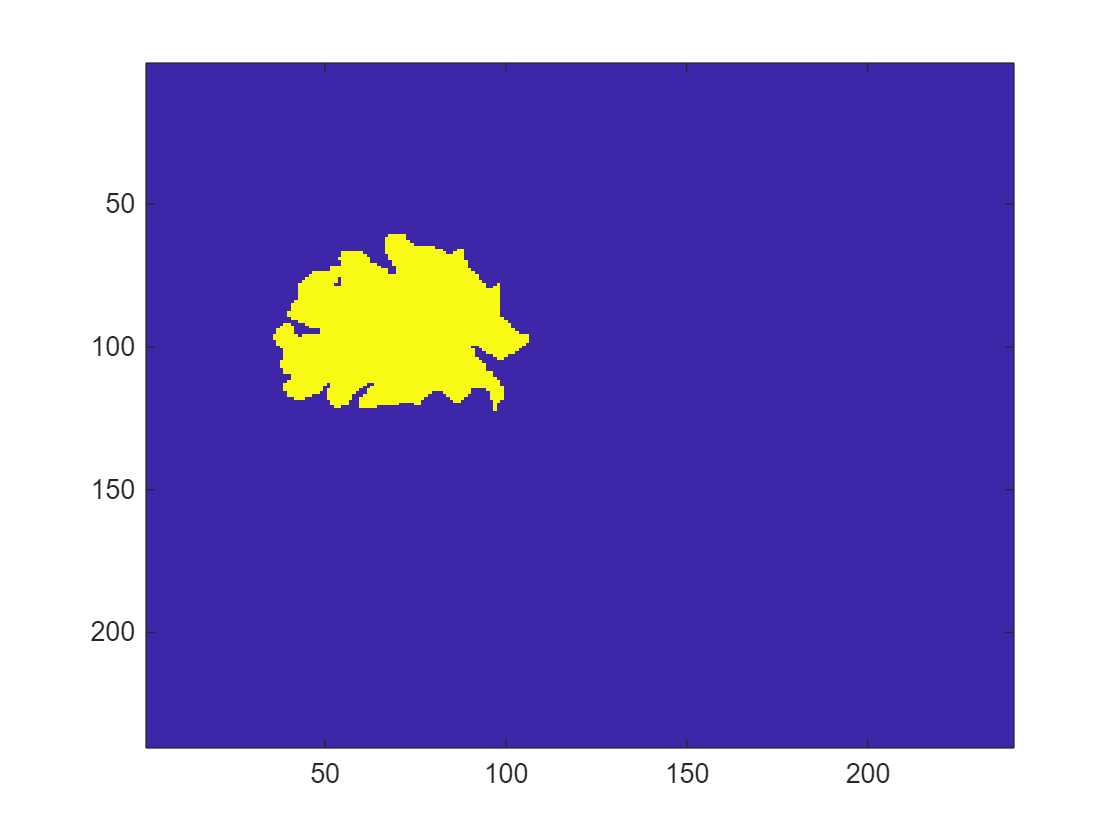

% Defining the inputs of the FIS (the features extracted previously)
inputs_opt = [ ... 
    data(:), ...
    normMean(:), ...
    normStand(:), ...
    normSkewns(:), ...
    normKurtss(:), ...
    normEntropy(:), ...
    normMax(:), ...
    normMin(:), ...
    normGeoMean(:), ...
    normHarmmean(:), ...
    normEnergy(:), ...
    normContrast(:), ...
];

% Golden standard
imagesc(label)

% Check that the fitness function is working properly
FitnessFunc(weight1, numRules, optimized_fis, inputs_opt, label)

ans = 551

For the fitness function I will count the amount of pixels that differ from the golden standard

% Definition of the fitness function
FitnessFunction = @(x) FitnessFunc(x, numRules, optimized_fis, inputs_opt, label); % created function

*Genetic algorithm*

Evolve the combinations by selecting the top-performing combinations and applying genetic operations

% Initial population: chromosome where each gene is a rule
opts.InitialPopulationMatrix = population;

% The simulation starts with three chromosomes of rule weights
opts.PopulationSize=5;

% Indicate bounds of variables
opts.InitialPopulationRange = [0; 1];

% Single point Crossover
opts.CrossoverFcn=@crossoversinglepoint;

% Fraction of the population at the next generation that the crossover function creates
opts.CrossoverFraction=0.75;

% Uniform Mutation
opts.MutationFcn= {@mutationadaptfeasible, 0.1};

% Defining how to select the survivors
opts.SelectionFcn=@selectionroulette;

% Define the elite population (those who surely survive)
opts.EliteCount =1; % Keep only the top individual

% Define the maximum number of generations
opts.Generations=100;

% Defining the fitness limit after which the algorithm stops
opts.FitnessLimit = 300;

% The algorithm stops if there is not bettering for 5 generations
opts.MaxStallGenerations = 5;

*Change the corresponding rule weights from the FIS*

The genetic algorithm will run until we have the optimal rule weights, so a defined minimal error

% Run the genetic algorithm with the specified options and return the results
lb = zeros(1, numRules); % lower bound
ub = ones (1, numRules); % upper bound
[x,fval,exitflag,output,final_pop,scores] = ga(FitnessFunction,numRules,[],[],[],[], lb, ub, [], opts);

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


Now we can change the weights to the s Sugeno FIS

% Apply optimized weights to the FIS
for i = 1:numRules
    optimized_fis.rule(i).weight = x(i);
end
% Save result
writeFIS(optimized_fis, 'opt_Segmentation.fis');

Check the value of the final fitness function

FitnessFunc(x, numRules, optimized_fis, inputs_opt, label)

ans = 337

Visualizing the result of the optimized FIS

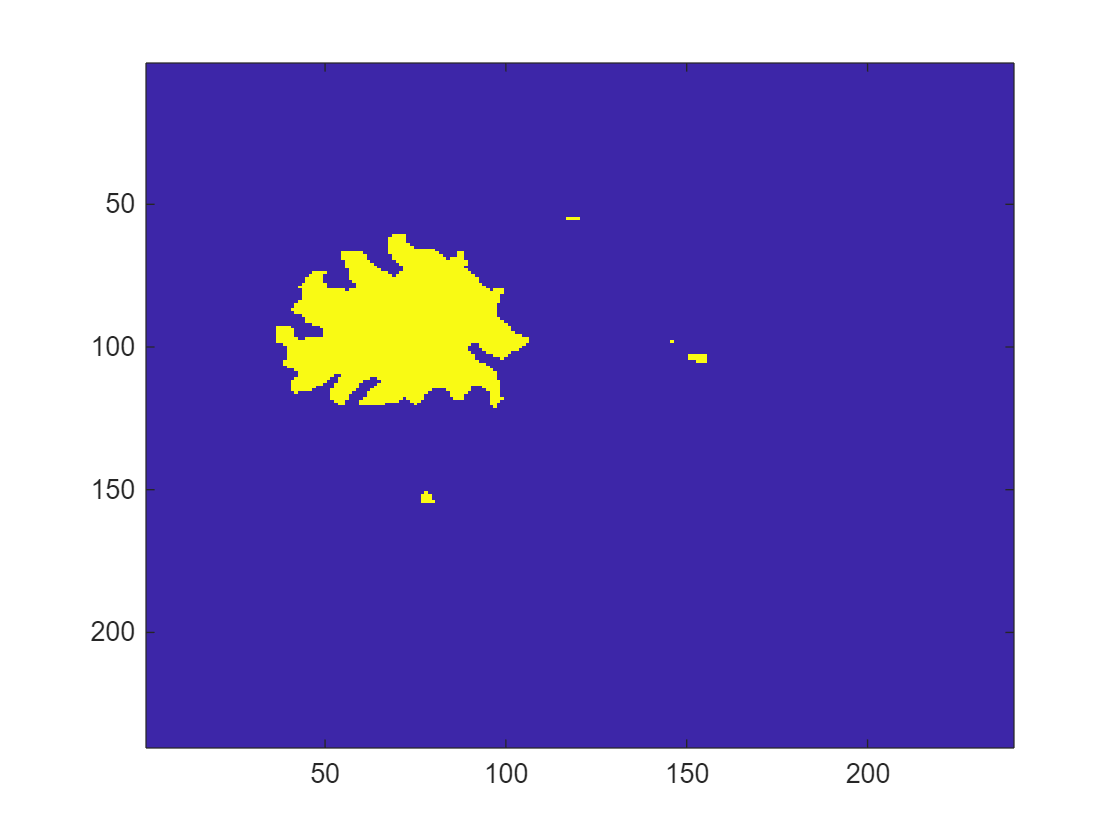

% Evaluating the pixels using the Sugeno FIS
tumorScores_opt = evalfis(optimized_fis, inputs_opt);  % size: [numPixels x 1]

% Exploring the values of the scores
minScore_opt = min(tumorScores_opt, [], "all");
maxScore_opt = max(tumorScores_opt, [], "all");

% Threshold definition to distinguish whether there is the tumor
tumorMask_opt = reshape(tumorScores_opt > 0.7, dimY, dimX);
% Reshaping of the results to have the same size as the original image

imagesc(tumorMask_opt)

### Phase 3: Evaluation of the results

The assessment must be performed on a separate image by the two models created, which are:

- The FIS that uses image-processing features

- The genetic algorithm that allows to have the optimal weights for the FIS

**Visualization**

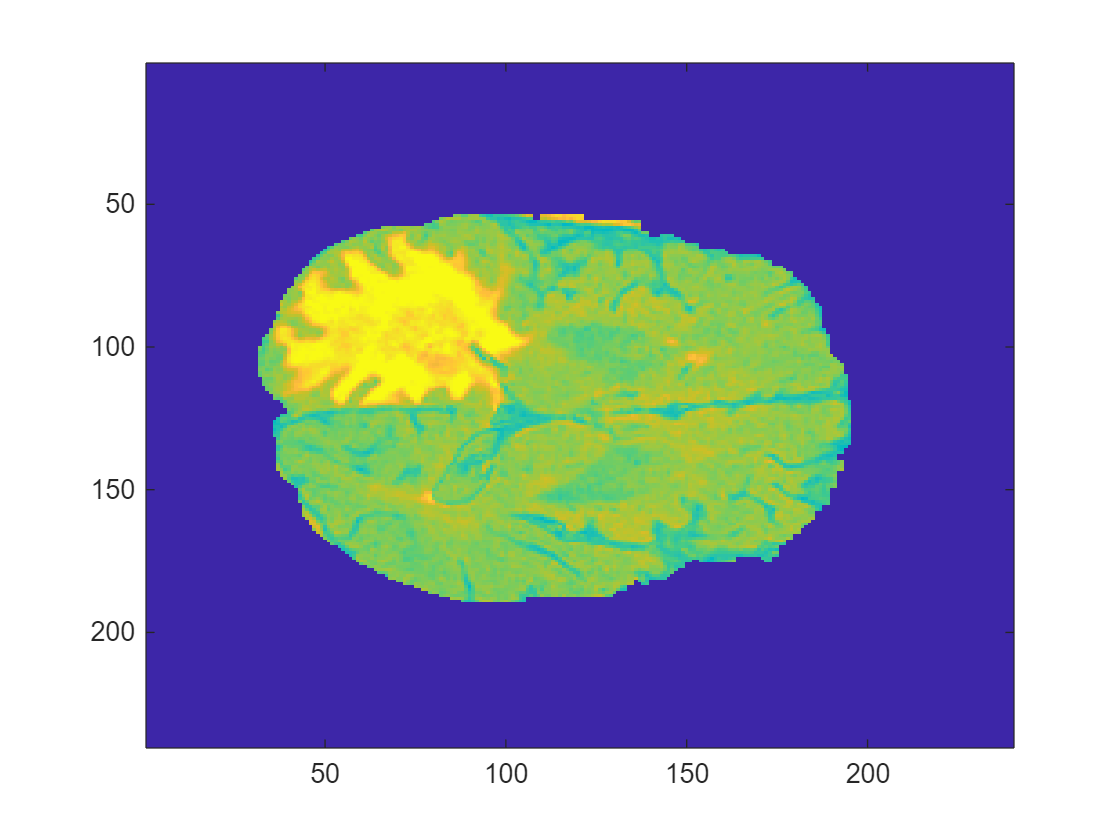

% Showing the original data
figure;
imagesc(data);

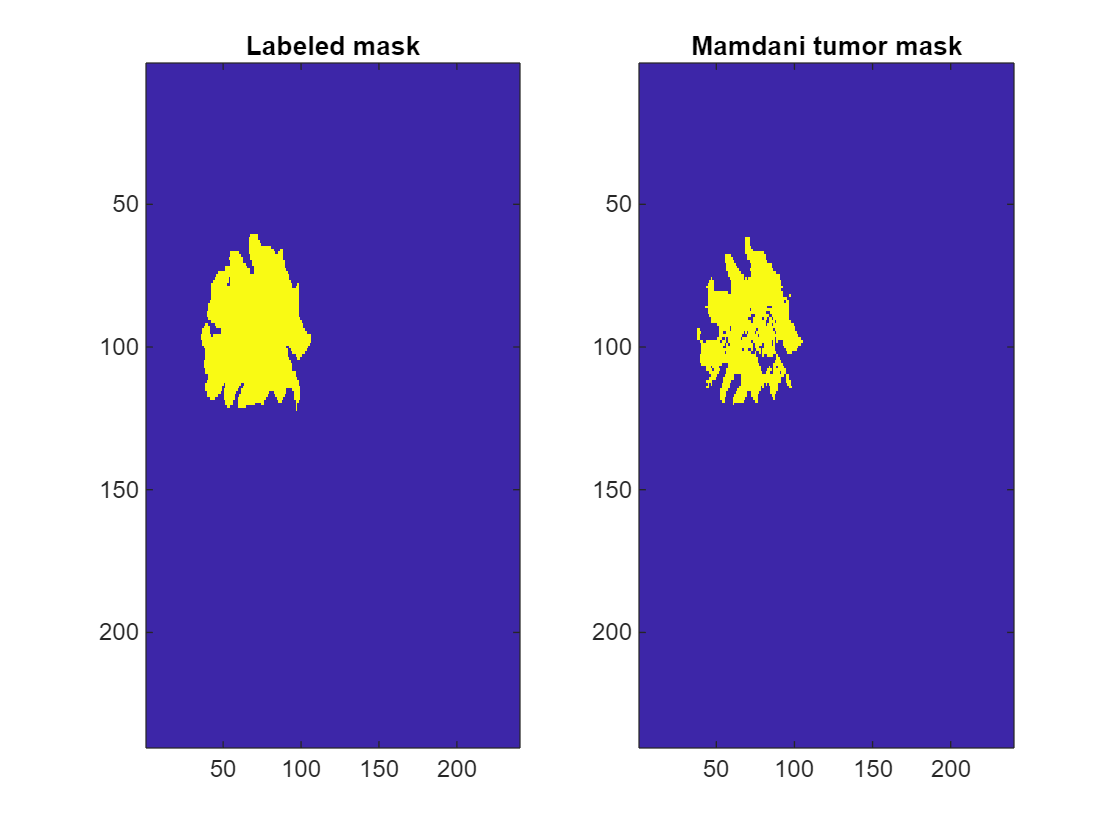

figure;
% Showing the label
subplot(1, 2, 1);
imagesc(label);
title('Labeled mask');

% Showing the mamdani output
subplot(1, 2, 2);
imagesc(tumorMask_mam);
title('Mamdani tumor mask');

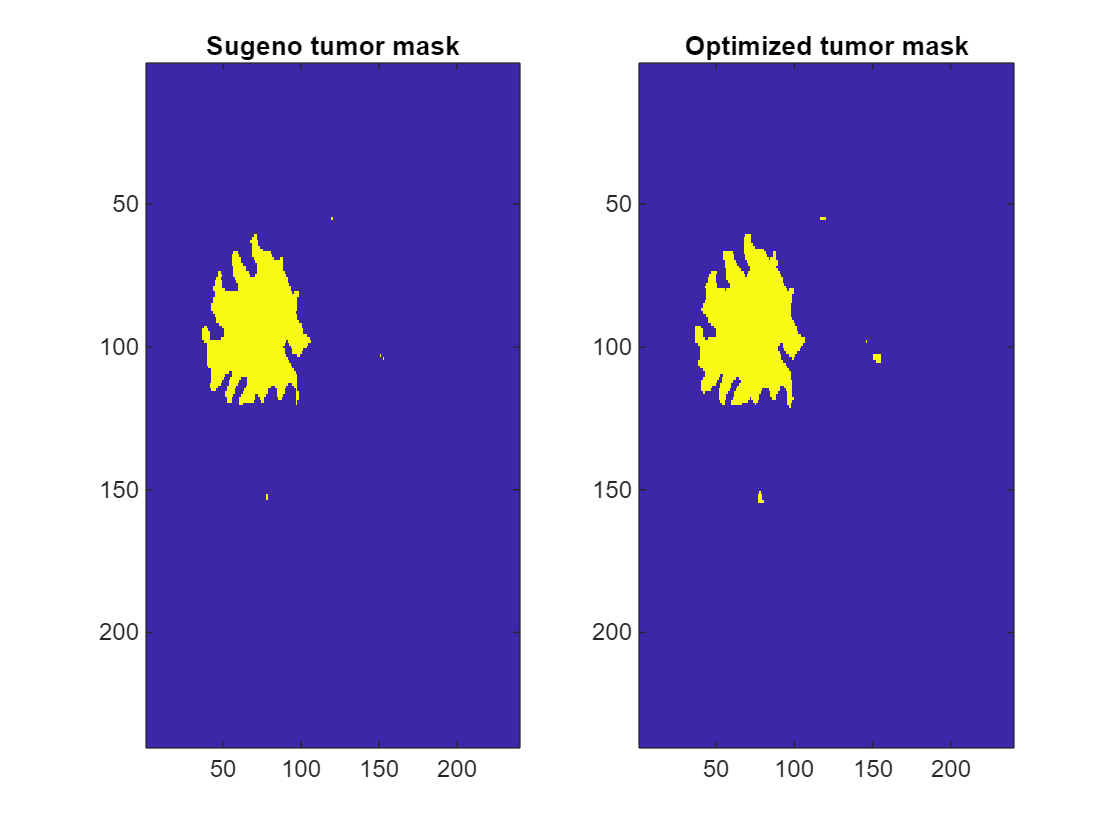

figure;
% Showing the sugeno output
subplot(1, 2, 1);
imagesc(tumorMask_sug);
title('Sugeno tumor mask');

% Showing the optimized output
subplot(1, 2, 2);
imagesc(tumorMask_opt);
title('Optimized tumor mask');

**Testing on a new image**

Selecting the new subject:

% Subject "BraTS446"
dataFileName_test = fullfile(imageDir, "BraTS447");
labelFileName_test = fullfile(labelDir, "BraTS447");

% Loading the data
dataTest = load(dataFileName_test);
labelTest = load(labelFileName_test );

Extracting a slice of the 3D MR image:

% Extract a slice of the 3D image
sliceNumberTest = 70;
dataTest = dataTest.cropVol(:, :, sliceNumberTest, 1);
labelTest = labelTest.cropLabel(:, :, sliceNumberTest);

Extracting the features

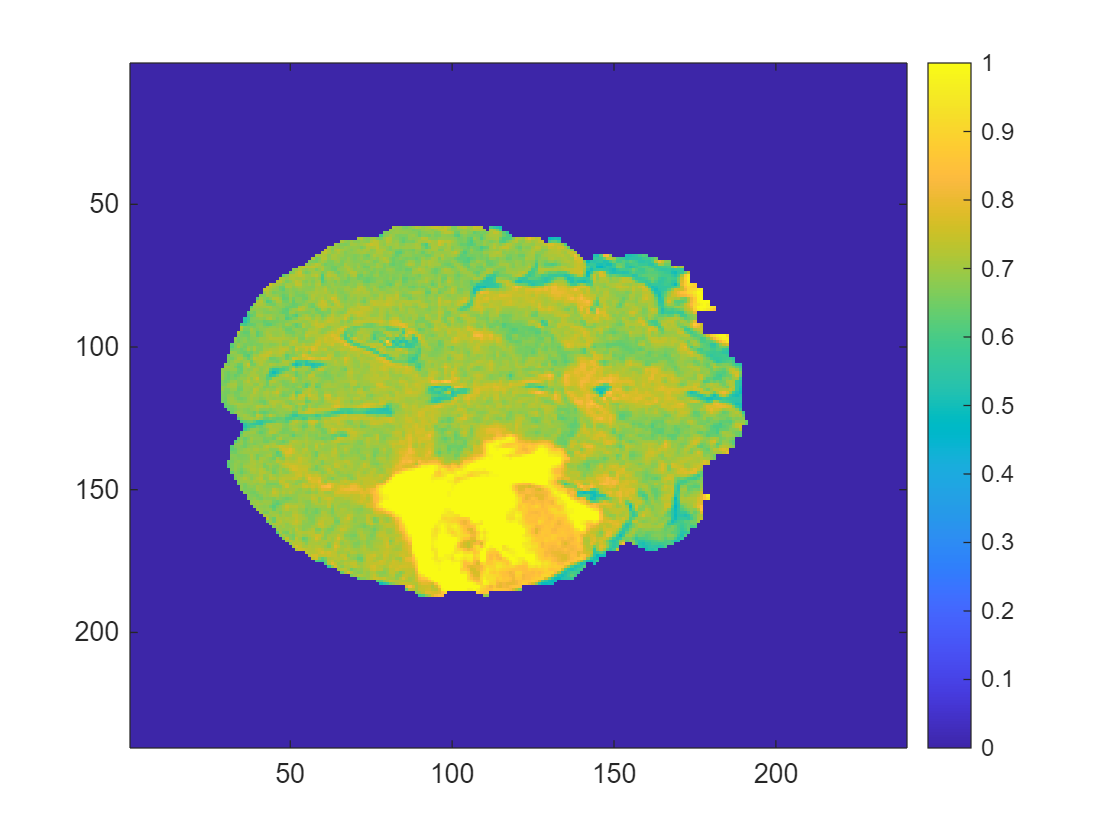

% Original image
figure;
imagesc(dataTest) % Original image
colorbar

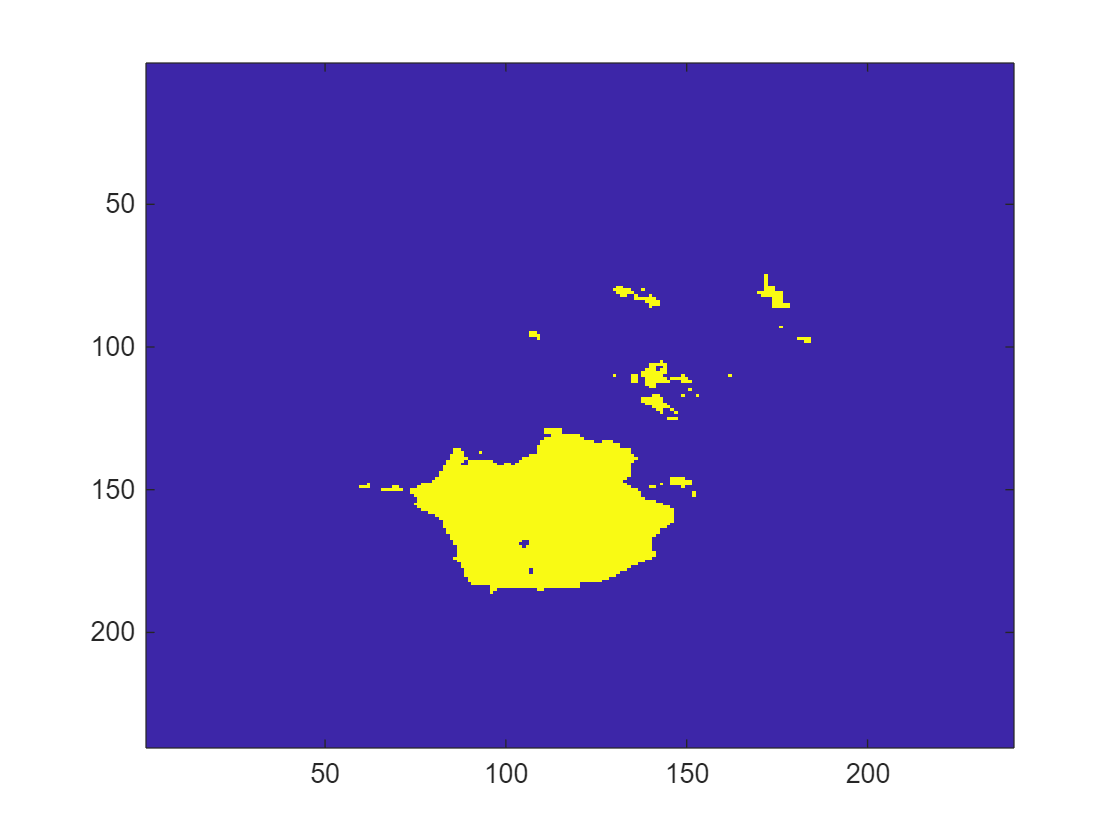

% Mean
mean_test = colfilt(dataTest, slidingWindow_size,'sliding',@mean);
normMean_test = normF(mean_test); % Normalization of the values within the image

% Standard Deviation
devStandard_test = colfilt(dataTest, slidingWindow_size,'sliding',@std);
normStand_test = normF(devStandard_test);

% Skewness 
skewns_test = colfilt(dataTest, slidingWindow_size,'sliding', @skewness);
skewns_test(isnan(skewns_test)) = 0; % change the nan values to 0
normSkewns_test = normF(skewns_test);

% Kurtosis
kurtss_test  = colfilt(dataTest, slidingWindow_size,'sliding',@kurtosis);
kurtss_test(isnan(kurtss_test)) = 0; % change the nan values to 0
normKurtss_test = normF(kurtss_test);

% Entropy
entropy = @(x) 0 - (sum(x - log2(x)));
entropy_test = colfilt(dataTest, slidingWindow_size,'sliding',entropy);
entropy_test(entropy_test == -Inf) = 0; % change the -Inf values to 0
normEntropy_test = normF(entropy_test);

% Maximum value
max_test = colfilt(dataTest, slidingWindow_size,'sliding', @max);
normMax_test = normF(max_test);

% Minimum value
min_test = colfilt(dataTest, slidingWindow_size,'sliding', @min);
normMin_test = normF(min_test);

% Geometric mean
geomean_test = colfilt(dataTest, slidingWindow_size,'sliding', @geomean);
normGeoMean_test = normF(geomean_test);

% Harmonic mean
harmmean_test = colfilt(dataTest, slidingWindow_size,'sliding', @harmmean);
normHarmmean_test = normF(harmmean_test);

% Energy
energy_func = @(x) sum(x.^2);
energy_test = colfilt(dataTest, slidingWindow_size,'sliding', energy_func);
normEnergy_test = normF(energy_test);

% Constrast 
contrast_test = imadjust(dataTest);
normContrast_test = normF(contrast_test);

% Test Input features 
input_test = [
    dataTest(:), ...
    normMean_test(:), ...
    normStand_test(:), ...
    normSkewns_test(:), ...
    normKurtss_test(:), ...
    normEntropy_test(:), ...
    normMax_test(:), ...
    normMin_test(:), ...
    normGeoMean_test(:), ...
    normHarmmean_test(:), ...
    normEnergy_test(:), ...
    normContrast_test(:), ...
];

% Testing using the optimized FIS
tumorScores_test = evalfis(optimized_fis, input_test);  % size: [numPixels x 1]

% Exploring the values of the scores
minScore_test = min(tumorScores_test, [], "all");
maxScore_test = max(tumorScores_test, [], "all");

% Threshold definition to distinguish whether there is the tumor
tumorMask_test = reshape(tumorScores_test > 0.7, dimY, dimX);

imagesc(tumorMask_test)

% Evaluating the amount of different pixels
FitnessFunc(x, numRules, optimized_fis, input_test, labelTest)

ans = 405

I would like you to notice that the optimized FIS is not overfitting, since for the image on which it was trained, the fitness function gave 337, while on the new image it outputs 405. Over the 240x240 pixels present in the figure, the precision is the following:

- Training image: 99.41%

- Testing image: 99.30%

**Evaluation**

The evaluation metrics that I will use to evalute the segmentation:

- **Accuracy**: to measure the amount of correcly classified pixels

- **Dice coefficient**: coefficient that computes how similar two sets are

*Accuracy*

% Accuracy for train image using the optimized FIS
accuracy_trainOpt = sum(label == tumorMask_opt,'all')/numel(tumorMask_opt)

accuracy_trainOpt = 0.9941

% Accuracy for train image using the sugeno FIS
accuracy_trainSug = sum(label == tumorMask_sug,'all')/numel(tumorMask_sug)

accuracy_trainSug = 0.9912

% Accuracy for test image
accuracy_test = sum(labelTest == tumorMask_test,'all')/numel(tumorMask_test)

accuracy_test = 0.9930

*Dice coefficient*

% Dice coefficient for the train image using the optimized FIS
intersectionTrain_opt = sum(tumorMask_opt(:) & label(:));
totalTrain_opt = sum(tumorMask_opt(:)) + sum(label(:));
dice_scoreTrain_opt = (2 * intersectionTrain_opt)/(totalTrain_opt+eps)

dice_scoreTrain_opt = 0.9387

% Dice coefficient for the train image using the optimized FIS
intersectionTrain_sug = sum(tumorMask_sug(:) & label(:));
totalTrain_sug = sum(tumorMask_sug(:)) + sum(label(:));
dice_scoreTrain_sug = (2 * intersectionTrain_sug)/(totalTrain_sug+eps)

dice_scoreTrain_sug = 0.9040

% Dice coefficient for the test image
intersectionTest = sum(tumorMask_test(:) & labelTest(:));
totalTest = sum(tumorMask_test(:)) + sum(labelTest(:));
dice_scoreTest = (2 * intersectionTest)/(totalTest+eps)

dice_scoreTest = 0.9285